# Image Processing

## Introduction to Monochrome Images

An image is the optical representation of objects illuminated by a light source. Since we want to process images using a computer, we represent them as functions of discrete spatial variables. For monochrome (black-and-white) images, a scalar function f(m,n) can be used to represent the light intensity at each spatial coordinate (m, n). Figure 1 illustrates the convention we will use for spatial coordinates to represent images.

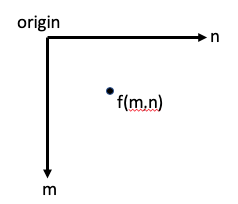

Figure 1: Spatial coordinates used in a digital image representation.

If we assume the coordinates to be a set of positive integers, for example m = 1, . . . , M and n = 1, . . . , N, then an image can be conveniently represented by a matrix.


$$ f(m,n) =
  \left[ {\begin{array}{cccc}
   f(1,1) & f(1,2) & \cdots & f(1,N) \\
   f(2,1) & f(2,2) & \cdots & f(2,N) \\
   \vdots & \vdots &  & \vdots \\
   f(M,1) & f(M,2) & \cdots & f(M,N) \\
  \end{array} } \right] \ \text{.}$$


We call this an M × N image, and the elements of the matrix are known as pixels. The pixels in digital images usually take on integer values in the finite range,


$$0 \le f(m,n) \le L_{\text{max}} \ \text{,}$$


where 0 represents the minimum intensity level (black), and $L_{\text{max}}$ is the maximum intensity level (white) that the digital image can take on. The interval [0, $L_{\text{max}}$] is known as a gray scale. In this lab, we will concentrate on 8-bit images, meaning that each pixel is represented by a single byte. Since a byte can take on 256 distinct values, $L_{\text{max}}$ is 255 for an 8-bit image.

In order to process images within Matlab, we need to first understand their numerical representation. Read in the image file 'yacht.tif' . This is an 8-bit monochrome image. Read it into a matrix using myImagUint = imread('yacht.tif');. Type whos to display your variables. Notice under the "Class" column that the myImagUint matrix elements are of type uint8 (unsigned integer, 8 bits). This means that Matlab is using a single byte to represent each pixel. Matlab cannot perform numerical computation on numbers of type uint8, so we usually need to convert the matrix to a floating point representation. Create a double precision representation of the image using myImage = double(A);. Again, type whos and notice the difference in the number of bytes between myImagUint and myImage. In future sections, we will be performing computations on our images, so we need to remember to convert them to type double before processing them. Display yacht.tif using the following sequence of commands: 

image(myImage); 

myImage = double(myImage);

colormap(gray(256)); 

axis('image'); 

The image command works for both type uint8 and double images. The colormap command specifies the range of displayed gray levels, assigning black to 0 and white to 255. It is important to note that if any pixel values are outside the range 0 to 255 (after processing), they will be clipped to 0 or 255 respectively in the displayed image. It is also important to note that a floating point pixel value will be rounded down ("floored") to an integer before it is displayed. Therefore the maximum number of gray levels that will be displayed on the monitor is 255, even if the image values take on a continuous range.

Put your code here:

% Read the image file 'yacht.tif'
myImagUint = imread('Sample_Images/yacht.tif');

% Display variables to check class (uint8)
whos

  Name                         Size              Bytes  Class          Attributes

  A1                           1x15                120  double                   
  A2                           1x15                120  double                   
  A3                           1x15                120  double                   
  H1                           1x256              4096  double         complex   
  H2                           1x256              4096  double         complex   
  H3                           1x256              4096  double         complex   
  I                            1x1                   8  double                   
  MinPeakDistance              1x1                   8  double                   
  MinPeakHeight                1x1                   8  double                   
  Npts                         1x1                   8  double                   
  Vomega1                      1x256              4096  double         complex   
  Vomega2      

% Convert to double precision
myImage = double(myImagUint);

% Display variables again to see byte difference
whos

  Name                         Size              Bytes  Class          Attributes

  A1                           1x15                120  double                   
  A2                           1x15                120  double                   
  A3                           1x15                120  double                   
  H1                           1x256              4096  double         complex   
  H2                           1x256              4096  double         complex   
  H3                           1x256              4096  double         complex   
  I                            1x1                   8  double                   
  MinPeakDistance              1x1                   8  double                   
  MinPeakHeight                1x1                   8  double                   
  Npts                         1x1                   8  double                   
  Vomega1                      1x256              4096  double         complex   
  Vomega2      

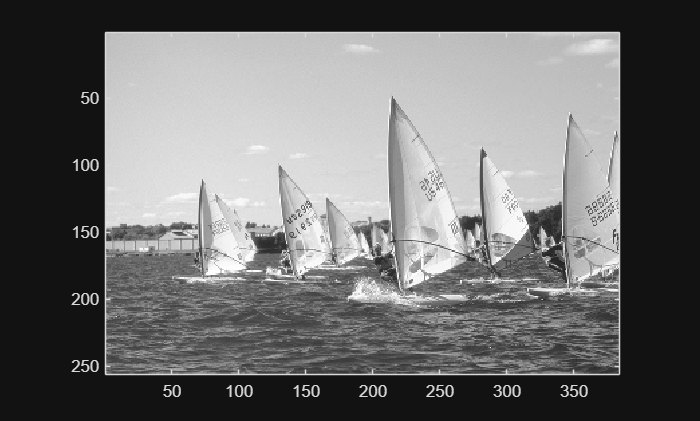

% Display the image
image(myImage);
myImage = double(myImage);
colormap(gray(256));
axis('image');

## Simple Image Operations

Now we will practice some simple operations on the yacht.tif image. Make a horizontally flipped version of the image by reversing the order of each column (use the MATLAB function `fliplr()`). Similarly, create a vertically flipped image (use the MATLAB function f`lipud()`). Display your results. Now, create a “negative” of the image by subtracting each pixel from 255 (here’s an example of where conversion to double is necessary.) Display the result. Finally, multiply each pixel of the original image by 1.5, and display the result.

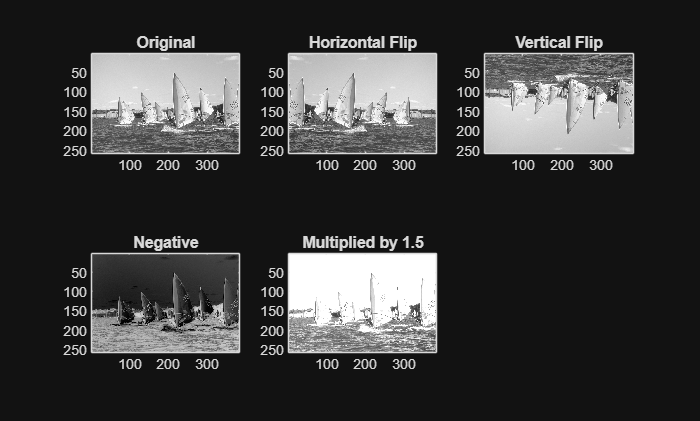

% Read and convert image
myImagUint = imread('Sample_Images/yacht.tif');
myImage    = double(myImagUint);

% Horizontal flip — reverse order of columns
hFlip = fliplr(myImage);

% Vertical flip — reverse order of rows
vFlip = flipud(myImage);

% Negative — subtract each pixel from 255
negImage = 255 - myImage;

% Multiply each pixel by 1.5
brightImage = myImage * 1.5;

% Display all results
figure;

subplot(2,3,1);
image(myImage);
colormap(gray(256));
axis('image');
title('Original');

subplot(2,3,2);
image(hFlip);
colormap(gray(256));
axis('image');
title('Horizontal Flip');

subplot(2,3,3);
image(vFlip);
colormap(gray(256));
axis('image');
title('Vertical Flip');

subplot(2,3,4);
image(negImage);
colormap(gray(256));
axis('image');
title('Negative');

subplot(2,3,5);
image(brightImage);
colormap(gray(256));
axis('image');
title('Multiplied by 1.5');

## Pixel Distributions

### Histogram of an Image

The *histogram* of a digital image shows how its pixel intensities are distributed. The pixel intensities vary along the horizontal axis, and the number of pixels at each intensity is plotted vertically, usually as a bar graph.

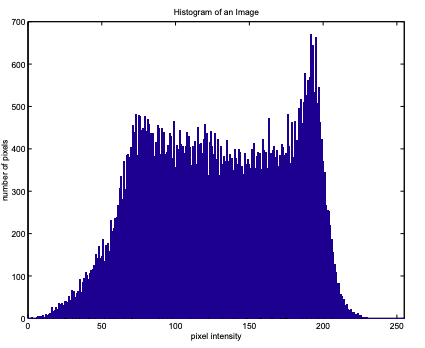

Figure 2. Histogram of an 8-bit image.

Read the image file house.tif into Matlab. Plot a histogram of the pixel values. Label the axes of the histogram and give it a title. You may use Matlab's histogram() function, however that function requires a vector as input. An example of using MATLAB's histogram() to plot a histogram of a matrix would be:

x=reshape(A,1,M*N); 

histogram(x,'BinLimits',[0,255]);

where A is an image, and M and N are the number of rows and columns in A. The reshape() command is creating a row vector out of the image matrix, and the histogram() command plots a histogram with bins centered at [0 : 255].

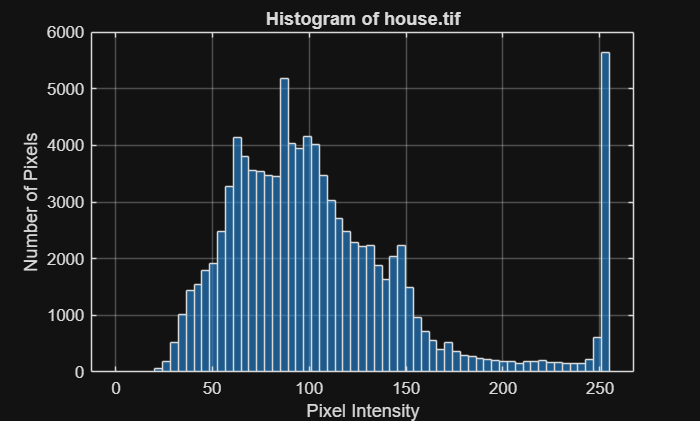

histreader = imread('Sample_Images/house.tif');

% Store as uint8 row vector (required type)
[M, N] = size(histreader);
histData = reshape(histreader, 1, M*N);  % already uint8

% Convert to double only for plotting
x = double(histData);

% Plot histogram
figure;
histogram(x, 'BinLimits', [0, 255]);
xlabel('Pixel Intensity');
ylabel('Number of Pixels');
title('Histogram of house.tif');
grid on;

### PointTrans function (Increasing an Image's contrast) -> Make it more defined

A pointwise transformation is a function that maps pixels from one intensity to another. An example is shown in Fig. 3. 

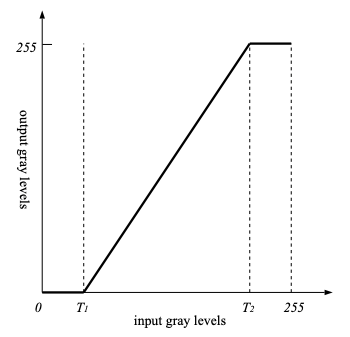

Figure 3: Pointwise transformation of Pixel Values

A pointwise transformation remaps pixel intensities to **increase contrast**. Pixels below T1 → black (0), pixels above T2 → white (255), and everything in between is **stretched** to fill the full [0, 255] range.

This affects the histogram:

- Pixels outside [T1, T2] create **spikes at 0 and 255**

- Pixels inside [T1, T2] produce a **stretched, rescaled** version of the original histogram

**Task**

- Write `output = PointTrans(input, T1, T2)` — applies the contrast-stretching transformation

- Read `narrow.tif` — display it and plot its histogram

- The image looks washed out because its histogram is **narrow** (low contrast)

- Apply `PointTrans()` with `T1 = 70`, `T2 = 180` to spread the histogram

- Display the improved image and its new histogram

function outImag = PointTrans(inImag, T1, T2)

% Apply a point transformation to the pixel values of an image
% Input 
%       inImag: input image
%       T1: lower bound for the transformation
%       T2: upper bound for the transformation
% Output
%       outImag: output image

    outImag = (inImag - T1) * (255 / (T2 - T1));

    % Clip values to [0, 255]
    outImag = max(outImag, 0);
    outImag = min(outImag, 255);
    
end

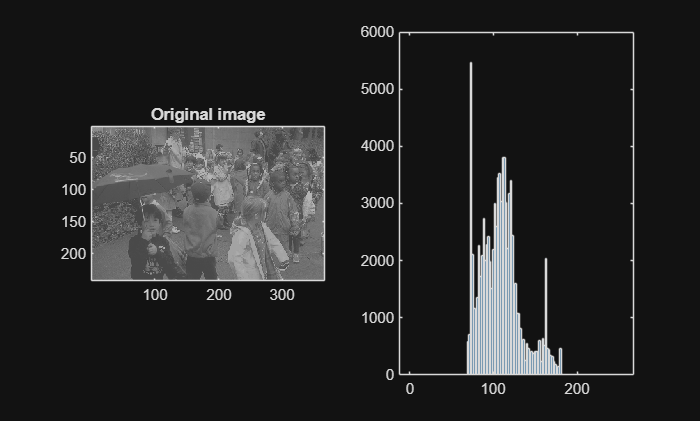

myImage = imread('Sample_Images/narrow.tif') ;   % Load narrow.tif

figure
subplot(1,2,1)
image(myImage)                     % Display image
colormap(gray(256))
axis('image')
maxGSVal = 255 ;                   % Max grey scale value 8-bit
title('Original image')

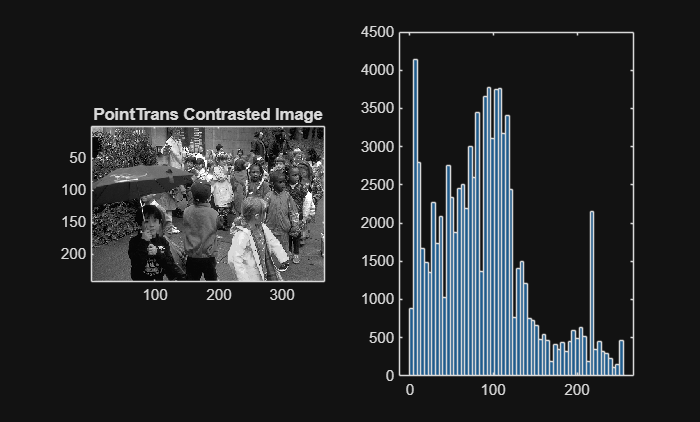


subplot(1,2,2)
histData = myImage(:) ;                           % Shortcut to flatten myImage into a column vector
histogram(histData,'BinLimits',[0,maxGSVal]) ;    % Show histogram
newImage = PointTrans(myImage, 70, 180) ;         % Apply your function

figure
subplot(1,2,1)
image(newImage)                    % Show transformed image
colormap(gray(256))
axis('image')
title('PointTrans Contrasted Image')


subplot(1,2,2)
histData = newImage(:) ;
histogram(histData,'BinLimits',[0,maxGSVal]) ;    % Show histogram for transformed image

## Gamma ($\gamma$) correction

Gamma correction brightens the dark areas of an image to compensate for the fact that displays naturally show things darker than they should be. Without it, an image that should look normal ends up appearing too dark on screen.

### Gamma Correction Plot

The power law is expressed as


$$I = V^\gamma$$


where *I* is the pixel intensity and *V* is the voltage applied to the device. If we re-express this equation in terms of pixel values for an 8-bit image, we get the following relationship:


$$y = 255\left(\frac{x}{255}\right)^{\gamma}$$


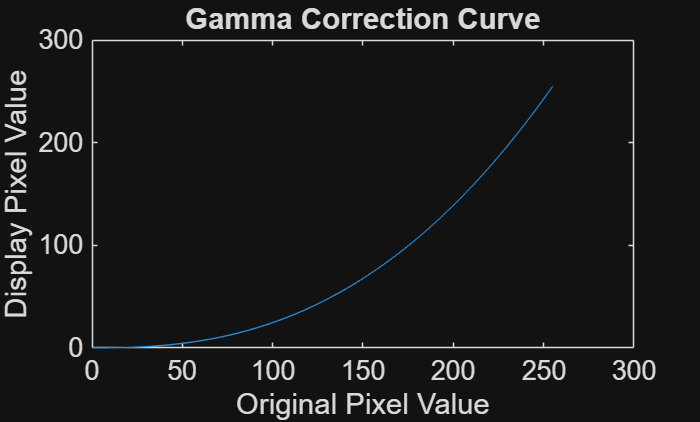

gammaVal = 2.5 ;
origPixVal = linspace(0,255,100) ;
dispPixVal = 255*(origPixVal/255).^gammaVal ;
figure
plot(origPixVal, dispPixVal)
xlabel('Original Pixel Value')
ylabel('Display Pixel Value')

title('Gamma Correction Curve')
set(gca,'fontsize',16)

Physical displays (CRT monitors) have a **nonlinear power-law response**, meaning brightness ≠ pixel value. This is described by gamma (γ):

**y = 255 × (x/255)^γ**

Without correction, images appear too dark or too bright. **Gamma correction** applies the inverse transformation to compensate.

- Run the provided code to visualise the gamma curve

- Read in `dark.tif`

- Write `gammCorr(myImage, gammaVal)` — applies inverse gamma correction:

                        y = 255 × (x/255)^(1/γ)

         4. Apply `gammCorr()` with `gammaVal = 2.2` to fix the dark image

         5. Display both original and corrected images

function newImage = gammCorr(myImage, gammaVal)

% Apply a gamma correction to an image
% Input
%      myImage: input image
%      gammaVal: gamma correction value
% Output
%      newImage: gamma corrected image

    % Normalize to [0,1], apply inverse gamma, scale back to [0,255]
    normalized = myImage / 255;
    corrected  = normalized .^ (1 / gammaVal);
    newImage   = corrected * 255;

end

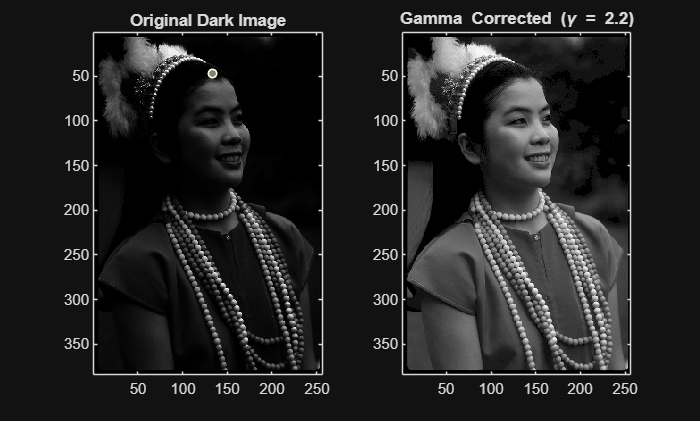

myImagUint = imread('Sample_Images/dark.tif');
myImage    = double(myImagUint);

figure;
subplot(1,2,1);
image(myImage);
colormap(gray(256));
axis('image');
title('Original Dark Image');

gammaVal = 2.2;
correctedImage = gammCorr(myImage, gammaVal);

subplot(1,2,2);
image(correctedImage);
colormap(gray(256));

axis('image');
title(sprintf('Gamma Corrected (\\gamma = %.1f)', gammaVal));

## Gaussian Filter (Smoothing)

The Gaussian filter is one of the most important smoothing filters due to its excellent spatial and frequency characteristics. Its shape is controlled by **variance (σ²)** — larger variance = wider, smoother filter.

It is normalised so all coefficients sum to 1 (no brightness change).

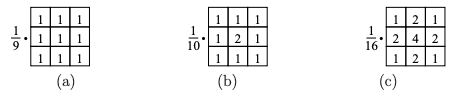

Figure 4: The Impulse response of some lowpass filters for image smoothing are shown.

- Write `hFilt = GaussFilter(Npts, var)` — creates an N×N normalised Gaussian filter centered at h[0,0] 

- N must be **odd** so the filter is symmetrically centered

- The filter is both **separable and symmetric**

         2. Compute the frequency response of a **7×7 Gaussian filter** with the given variance using K = L = 32

         3. Plot the magnitude using `mesh()` with labelled axes over the specified range

function hFilt = GaussFilter(Npts, var)

% Create a Gaussian smoothing filter
% Input 
%      Npts: filter size Npts x Npts
%      gaussVar: the variance of the Gaussian filter
% Output
%      hFilt: the Gaussian smoothing filter

if rem(Npts,2) ~= 1
    error('Npts must be odd\n') ;
end

% Create coordinate vector from -floor(Npts/2) to +floor(Npts/2)
mVal = -floor(Npts/2) : floor(Npts/2);

% Use meshgrid to create 2D coordinate matrices
[nMat, mMat] = meshgrid(mVal, mVal);

% Implement the Gaussian formula
hFilt = exp(-(mMat.^2 + nMat.^2) / (2 * var));

% Normalise so sum of all coefficients = 1
hFilt = hFilt / sum(hFilt(:));

end

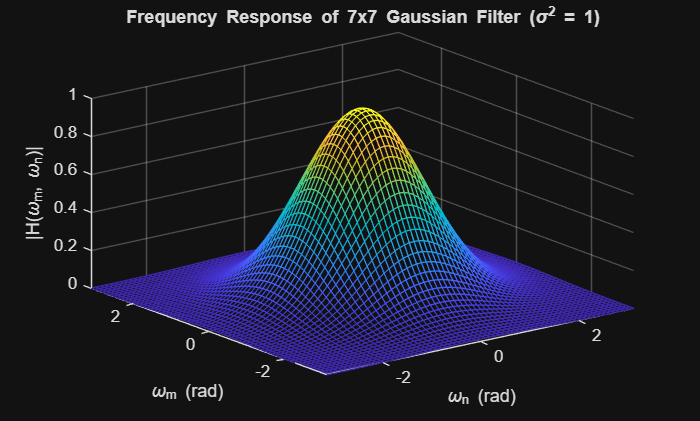

% Create 7x7 Gaussian filter with variance sigma^2 = 1
Npts = 7;
var  = 1;
hFilt = GaussFilter(Npts, var);

% Compute frequency response using K=L=32
K = 32;
L = 32;

% Zero-pad filter and compute 2D DFT
H = fftshift(fft2(hFilt, 2*K+1, 2*L+1));

% Frequency axes from -pi to pi
omega_x = linspace(-pi, pi, 2*K+1);
omega_y = linspace(-pi, pi, 2*L+1);
[Wx, Wy] = meshgrid(omega_x, omega_y);

%% Plot magnitude using mesh
% Plots the magnitude of the frequency response as a 3D surface
% The peak at the center (0,0) represents the DC component — Gaussian filters are lowpass so this is the highest point
% The response drops off smoothly away from center, showing that high frequencies are attenuated

figure;
mesh(Wx, Wy, abs(H));
xlabel('\omega_n (rad)');
ylabel('\omega_m (rad)');
zlabel('|H(\omega_m, \omega_n)|');
title('Frequency Response of 7x7 Gaussian Filter (\sigma^2 = 1)');

axis([-pi pi -pi pi 0 inf]);

## Median filter (anti-noise "salt and pepper" supression)

Write `outImage = MedianFilter(inImage)` — implements a 3×3 median filter manually (no `medfilt2`), border pixels can be left unchanged.

function outImage = MedianFilter(inImage)

% Filter an image with a 3x3 median filter
% Input
%      inImage: the input image
% Output
%      outImage: the output image

    kernelSize = 9 ;
    outImage = inImage ;
    [numRow, numCol] = size(inImage) ;

    % Use nested for loops to set each pixel value in outImage. Make sure to set the bounds on the for loops carefully.
    % Hint: median() used with reshape().

    [M, N]   = size(inImage);
    outImage = inImage;          % copy input (border pixels unchanged)

    % Loop over all non-border pixels

    for m = 2:M-1
        for n = 2:N-1
            % Extract 3x3 neighbourhood
            neighbourhood = inImage(m-1:m+1, n-1:n+1);
            % Replace pixel with median of neighbourhood
            outImage(m, n) = median(neighbourhood(:));
        end
    end

end

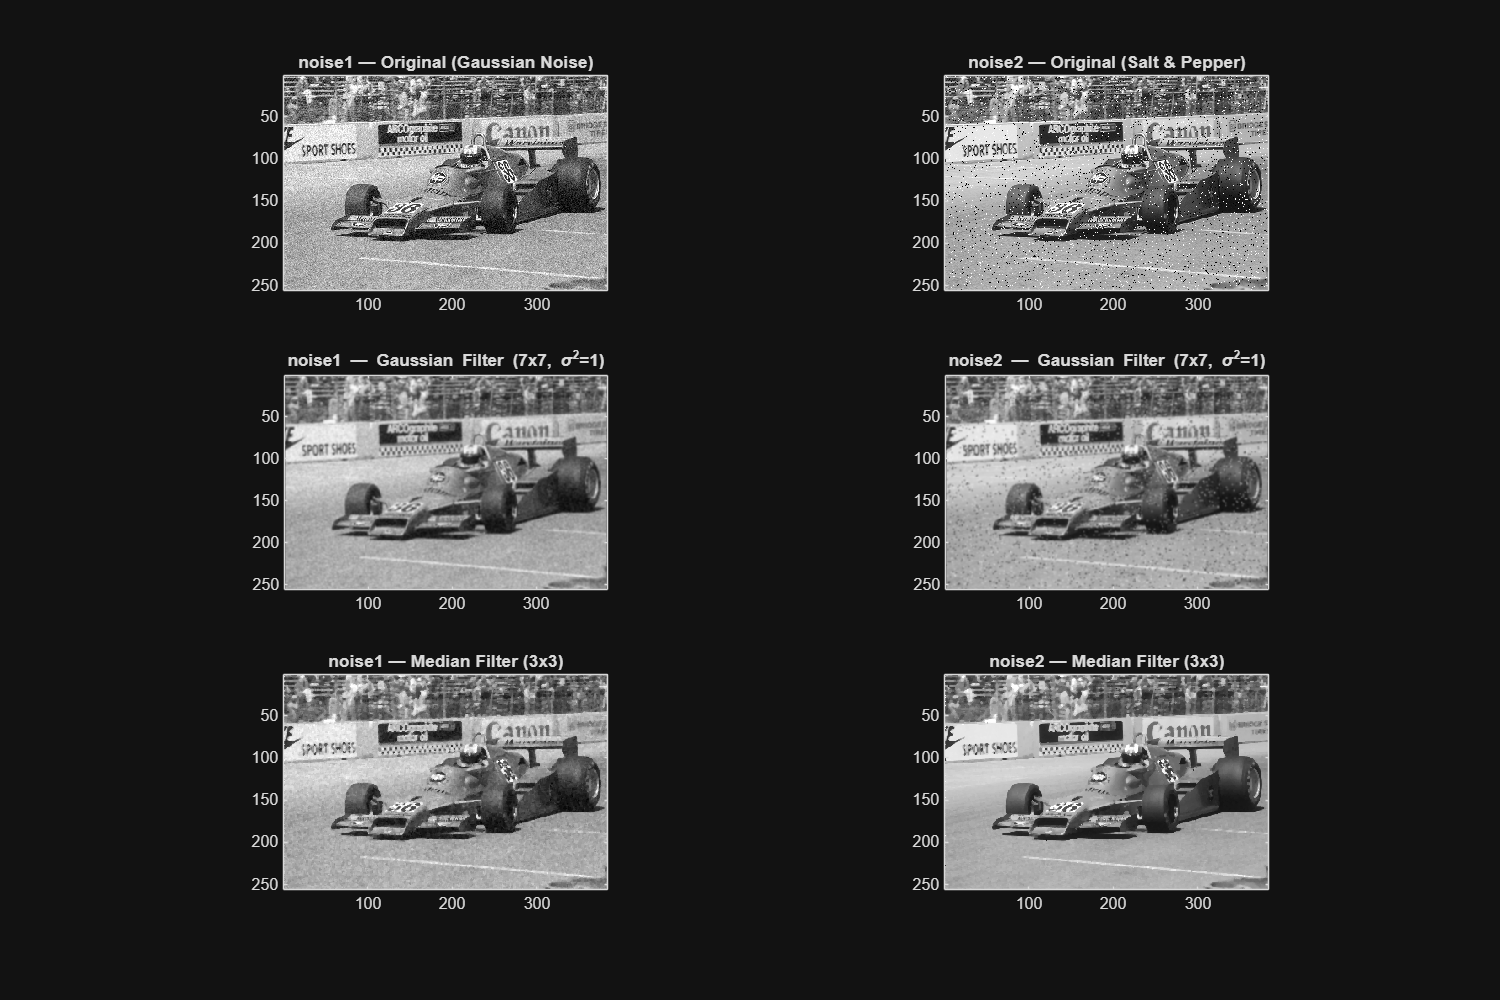

% Read images
race   = double(imread('Sample_Images/race.tif'));
noise1 = double(imread('Sample_Images/noise1.tif'));   % additive white Gaussian noise
noise2 = double(imread('Sample_Images/noise2.tif'));   % salt and pepper noise

% Create 7x7 Gaussian filter with sigma^2 = 1
hFilt = GaussFilter(7, 1);

% Apply Gaussian filter to both noisy images
noise1_gauss = filter2(hFilt, noise1);
noise2_gauss = filter2(hFilt, noise2);

% Apply Median filter to both noisy images
noise1_median = MedianFilter(noise1);
noise2_median = MedianFilter(noise2);

figure;
set(gcf, 'Position', [100, 100, 1200, 800]);

subplot(3,2,1);
image(noise1); colormap(gray(256)); axis('image');
title('noise1 — Original (Gaussian Noise)');

subplot(3,2,2);
image(noise2); colormap(gray(256)); axis('image');
title('noise2 — Original (Salt & Pepper)');

subplot(3,2,3);
image(noise1_gauss); colormap(gray(256)); axis('image');
title('noise1 — Gaussian Filter (7x7, \sigma^2=1)');

subplot(3,2,4);
image(noise2_gauss); colormap(gray(256)); axis('image');
title('noise2 — Gaussian Filter (7x7, \sigma^2=1)');

subplot(3,2,5);
image(noise1_median); colormap(gray(256)); axis('image');
title('noise1 — Median Filter (3x3)');

subplot(3,2,6);
image(noise2_median); colormap(gray(256)); axis('image');
title('noise2 — Median Filter (3x3)');

## Image Sharpening

Image sharpening techniques are used primarily to enhance an image by highlighting details. Since fine details of an image are the main contributors to its high frequency content, highpass filtering often increases the local contrast and sharpens the image. Some typical highpass filter impulse responses used for contrast enhancement are shown in Fig. 5. 

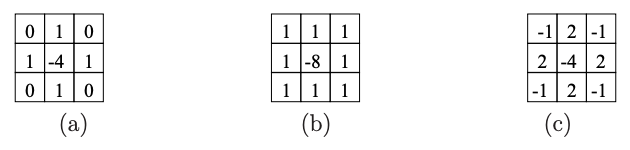

Figure 5: Impulse responses for highpass filters useful for image sharpening.

### **Part 1 — Frequency Response**

The unsharp mask works by subtracting the lowpass (blurry) version of the image from the original, leaving only the sharp details:

y[m,n] = α·x[m,n] - β·(h[m,n] * x[m,n])

Its frequency response is:

H(ω) = α - β·H_LP(ω)

Task:

- Create a 5×5 Gaussian filter with given variance using `GaussFilter()`

- Compute the frequency response using the analytical expression above

- Plot magnitude using `mesh()` with labelled axes over the range -π to π

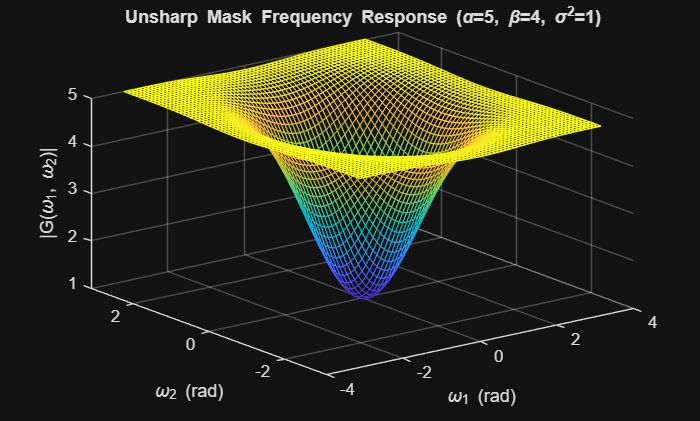

% Call the GaussFilter function
hFilt = GaussFilter(5, 1);

% Set the filter indices
mIndex = -floor(size(hFilt,1)/2) : floor(size(hFilt,1)/2);  % 1x5
nIndex = -floor(size(hFilt,2)/2) : floor(size(hFilt,2)/2);  % 1x5

% Set the number of frequency points
K = 32;
L = 32;

% Create frequency index vectors
kIndex = -K : K;   % 1x65
lIndex = -L : L;   % 1x65

% Create exponential matrices [5 x 65]
% W1mat(m, k) = e^(-j * mIndex(m) * kIndex(k)*pi/K)
W1mat = exp(-1j * mIndex' * (kIndex * pi/K));   % [5 x 65]
W2mat = exp(-1j * nIndex' * (lIndex * pi/L));   % [5 x 65]

% Calculate Frequency Response of hFilt
% Hfq = sum over m: sum over n: h[m,n] * W1mat(m,:) .* W2mat(n,:)
Hfq = zeros(length(kIndex), length(lIndex));
for mi = 1:length(mIndex)
    for ni = 1:length(nIndex)
        Hfq = Hfq + hFilt(mi, ni) * (W1mat(mi,:).' * W2mat(ni,:));
    end
end

% Calculate unsharp mask frequency response
alpha = 5;
beta  = 4;
Gfq   = alpha - beta * Hfq;

% Plot
[W1plot, W2plot] = meshgrid(lIndex*pi/L, kIndex*pi/K);

figure;
mesh(W1plot, W2plot, abs(Gfq));
xlabel('\omega_1 (rad)');
ylabel('\omega_2 (rad)');
zlabel('|G(\omega_1, \omega_2)|');

title('Unsharp Mask Frequency Response (\alpha=5, \beta=4, \sigma^2=1)');

### Part 2 — Apply to Image

Task:

- Read in `blur.tif`

- Apply the unsharp mask using `filter2()` with the specified α and β values

- Display both original and sharpened images using `image()`

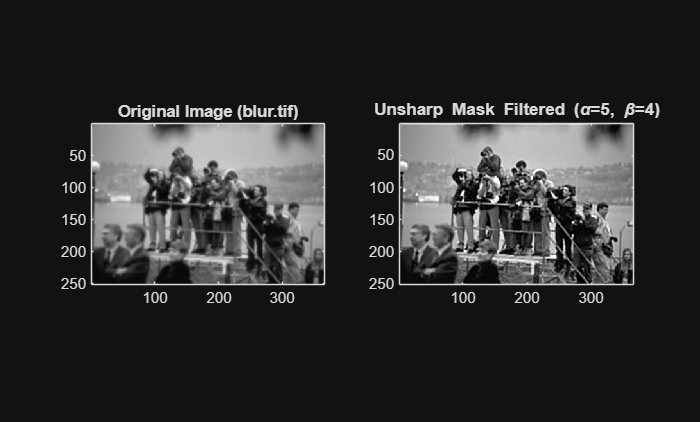

% Read and plot original image
inImage = imread('Sample_Images/blur.tif');
inImage = double(inImage);

% Apply unsharp mask: g = alpha*f - beta*(f*h)
outImage = alpha * inImage - beta * filter2(hFilt, inImage);

% Plot both images
figure;
subplot(1,2,1);
image(inImage);
colormap(gray(256));
axis('image');
title('Original Image (blur.tif)');

subplot(1,2,2);
image(outImage);

colormap(gray(256));
axis('image');
title('Unsharp Mask Filtered (\alpha=5, \beta=4)');